Attempting to cluster based off the amount of pixels present that overcome the thershold for each example so that a n example is described by three features


clear all; close all;
Datacluster = load('data.mat');
DataExamples = Datacluster.data.X;
DataLabels = Datacluster.data.Y;
%randomize data set
[r,c,~] = size(DataExamples);
idx = randperm(r);
DataExamples = DataExamples(idx,:,:);
DataLabels = DataLabels(idx);
clusteringData = zeros(r,3);
idx = find(DataExamples(1,:,1) > 170);
for j = 1 : r
   redDensity = (length(find(DataExamples(j,:,1) > 170)))/c;
   blueDensity = (length(find(DataExamples(j,:,2) > 170)))/c;
   greenDensity = (length(find(DataExamples(j,:,3) > 170)))/c;
   clusteringData(j,1) = redDensity;
   clusteringData(j,2) = blueDensity;
   clusteringData(j,3) = greenDensity;
end
%plot the 3 denemsional data 
randomPortion =  randi(ceil(length(clusteringData)/10))

randomPortion = 196

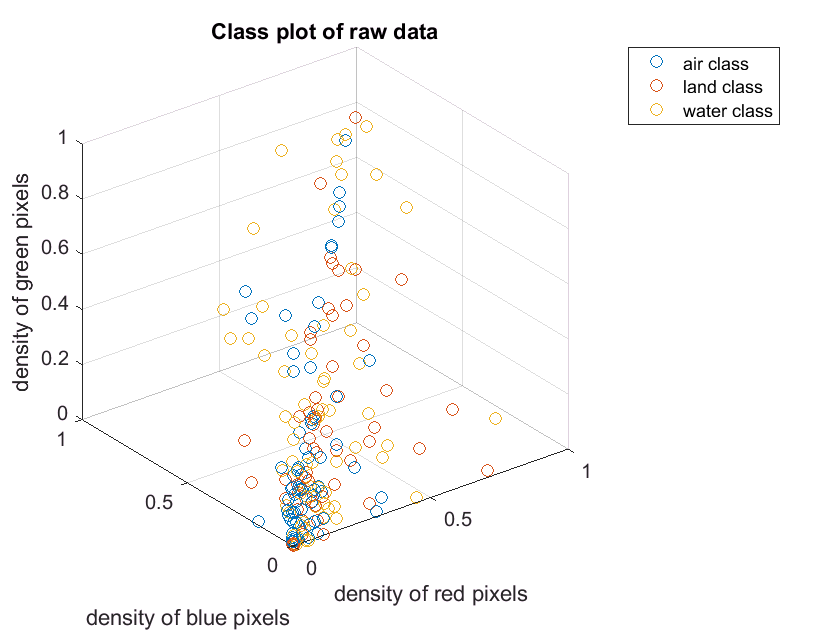


for class = 1:3
    idx = find( DataLabels(1:randomPortion) == class);
    scatter3(clusteringData(idx,1),clusteringData(idx,2),clusteringData(idx,3))
    hold on;
end
title('Class plot of raw data')
ylabel('density of blue pixels')
xlabel('density of red pixels')
zlabel('density of green pixels')
legend('air class','land class','water class')

hold off;

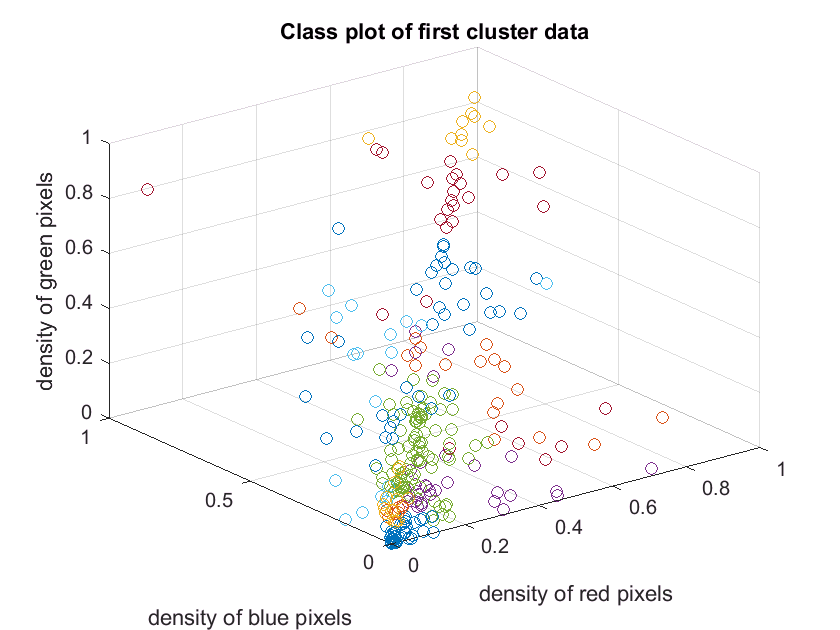

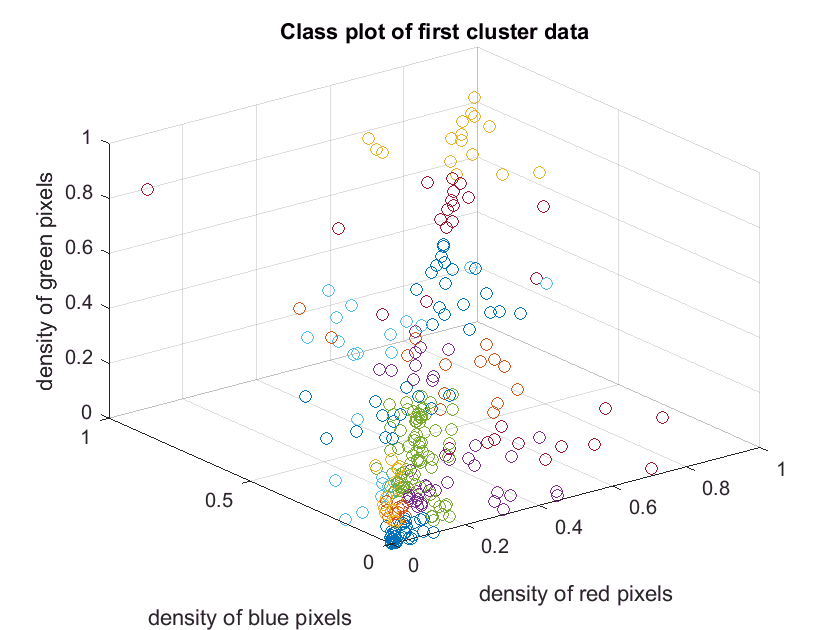

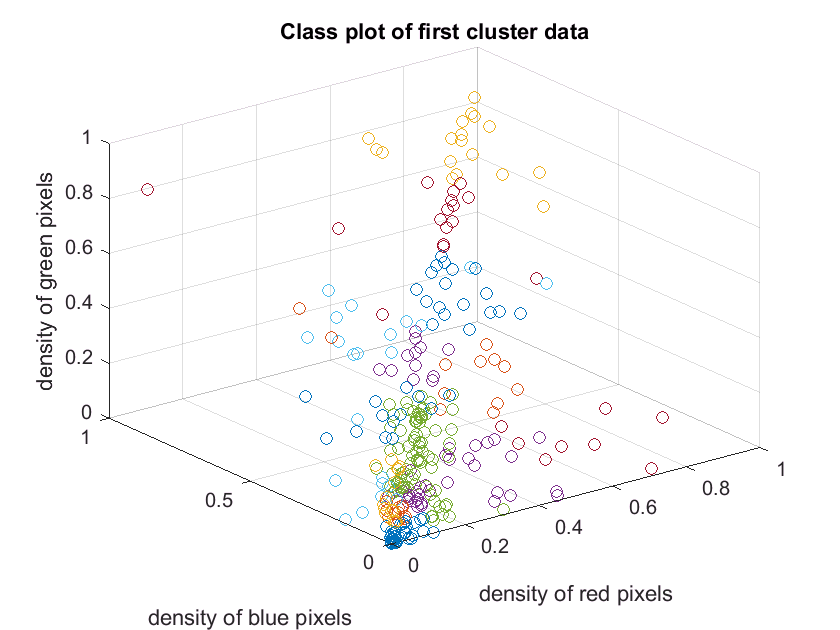

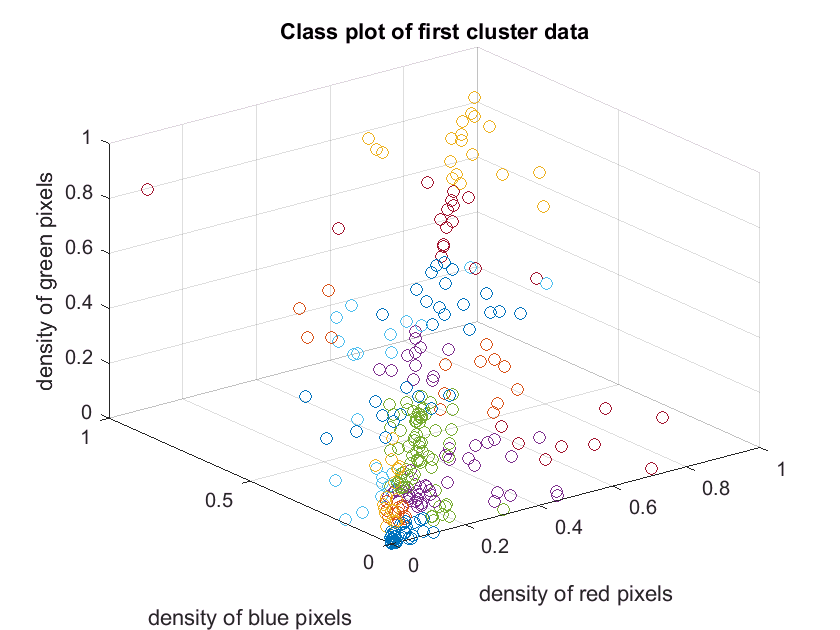

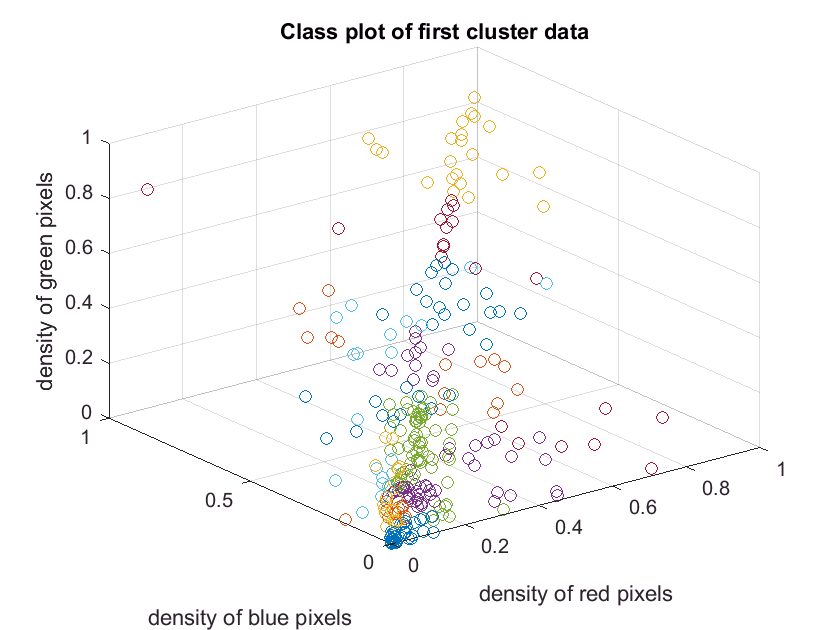

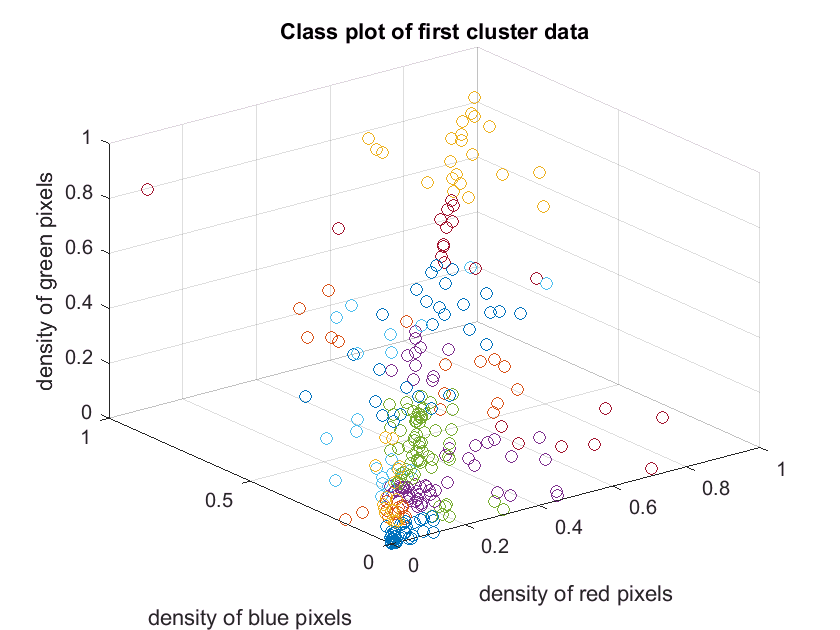

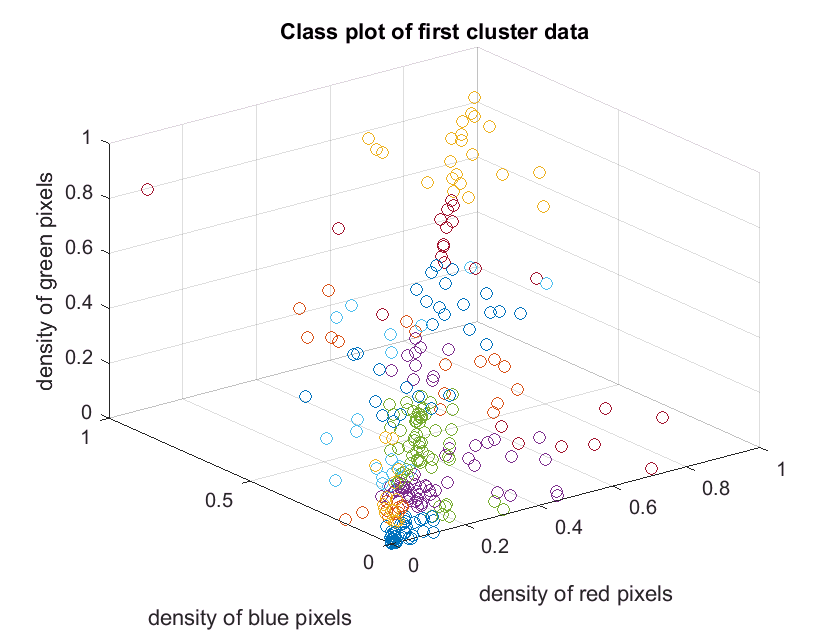

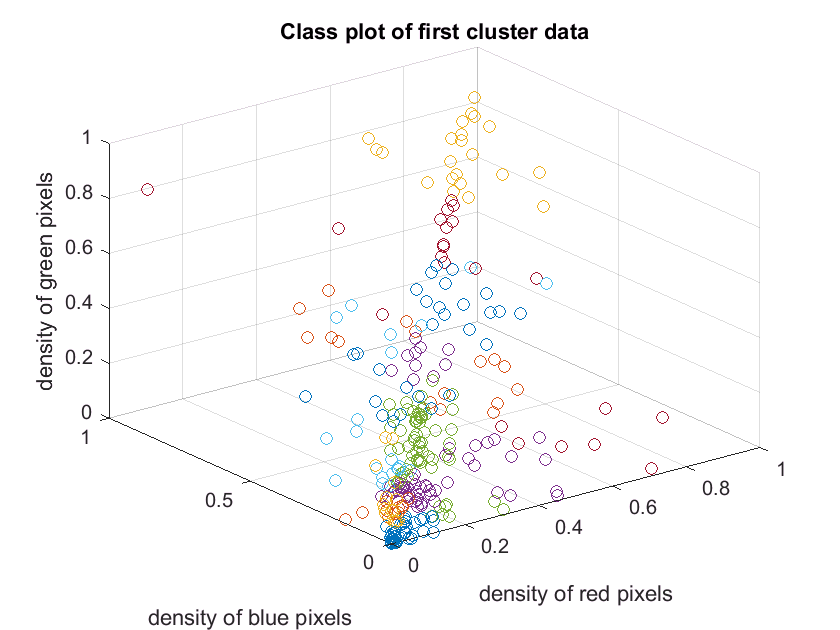

numberOfClusters = 27;
method = 1;
[ centroids ] = InitCentroids( clusteringData , numberOfClusters , method );
for K = 1:10
    
    [ Assignment ] = AssignToClosest( clusteringData ,  centroids );
    
    randomPortion =  300;
    figure;
    for class = 1:numberOfClusters
        idx = find( Assignment(1:randomPortion) == class);
        scatter3(clusteringData(idx,1),clusteringData(idx,2),clusteringData(idx,3))
        hold on;
    end
    title('Class plot of first cluster data')
    ylabel('density of blue pixels')
    xlabel('density of red pixels')
    zlabel('density of green pixels')
    hold off;
    
    for cluster = 1 : numberOfClusters
        idx = find( Assignment == cluster);
        centroids(cluster,:) = mean (clusteringData(idx,:));
    end

end